# **Ejemplo** - Problema de optimización de bombeo y distribución

*Adaptación del problema de diseño D6.2 de Fluid Mechanics, 9na edición, de Frank M. White.*

Se desea diseñar un sistema de bombeo y distribución para mantener lleno un tanque con capacidad de un millón de galones. El plan es usar una versión modificada (en tamaño y velocidad) de la bomba centrífuga modelo 1206 del fabricante Taco Comfort Solutions. Debajo se muestra la data de prueba de un modelo pequeño de esta bomba con D = 5.45", N = 1760 rpm:

Q_gpm = (0:5:60)';
H_pies = [28 28 29 29 28 28 27 26 25 23 21 18 15]';
Eta = 1/100*[0 13 25 35 44 48 51 53 54 55 53 50 45]';
data_modelo=table(Q_gpm,H_pies,Eta)

data_modelo = 13x3 table
    Q_gpm    H_pies    Eta 
    _____    ______    ____

      0        28         0
      5        28      0.13
     10        29      0.25
     15        29      0.35
     20        28      0.44
     25        28      0.48
     30        27      0.51
     35        26      0.53
     40        25      0.54
     45        23      0.55
     50        21      0.53
     55        18       0.5
     60        15      0.45


El tanque se debe llenar diario con agua fría (10°C) proveniente de un acuífero, que está a 0.8 millas del tanque y con una diferencia de altura de 150 pies. Se estima que el uso diario de agua es de 1.5 millones de galones y se requiere que el tiempo de llenado del tanque no exceda 8 horas al día, manteniendo la velocidad del motor en el rango de 900 a 1800 rpm. El sistema de tuberías debe tener cuatro válvulas mariposa con apertura variable, 10 codos de varios ángulos y la tubería es de hierro galvanizado. Se proveen los siguientes estimados de costos para los componentes del sistema:

- Bomba y motor: $3500 + $1500 por cada pulgada de diámetro del impulsor

- Válvulas: $300 + $200 por cada pulgada de tubería

- Codos: $50 + $50 por cada pulgada de tubería

- Tuberías: $1 por pulgada de diámetro por pie de longitud

La tarea de diseño es seleccionar el diámetro económico de la tubería, así como el diámetro del impulsor de la bomba y su velocidad, teniendo como objetivo minimizar el costo total. Esto incluye la inversión (en base a los costos previamente detallados) y gastos operativos (despreciando el mantenimiento y considerando el precio de la energía eléctrica como 0.10 USD/kWh), asumiendo un período de operación de 5 años. Considere que el diámetro de la tubería y del impulsor (en pulgadas) deben ser números enteros. 

## Caudal mínimo y tiempo máximo de operación:

Q_min = 1E6/(8*60);         % caudal mínimo (gpm) para llenar el tanque en 8 horas
t_min = (1.5E6/Q_min)/60;   % tiempo mínimo (horas) requerido para suplir el consumo diario operando @ Q_min
disp('Caudal mínimo requerido (gpm)'); disp(Q_min);

Caudal mínimo requerido (gpm)
   2.0833e+03



## Configuración de accesorios del sistema:

n_codos_45 =5;          % número de codos a 45 grados
n_codos_90 = 10 - n_codos_45;                   % número de codos a 90 grados

sK_codos = n_codos_90*0.9+n_codos_45*0.4;       % suma de coeficientes de codos

% Ángulos de apertura de válvulas mariposa:
ap_v=zeros(1,4);
ap_v(1) = 0; ap_v(2) = 0;
ap_v(3) = 0; ap_v(4) = 0;

% ángulo de apertura vs K para válvula mariposa
tabla_mariposa = [0:10:80;...
    0.47 0.53 1.80 4.12 9.19 19.67 68.06 323.50 4849.00];   

sK_mariposa=0; % suma de coeficientes de válvulas mariposa
for i=1:4
    sK_mariposa = sK_mariposa + tabla_mariposa(2,tabla_mariposa(1,:) == ap_v(i));
end

disp("Coeficiente global de pérdidas menores:")

Coeficiente global de pérdidas menores:


global sK_total %#ok<GVMIS> 
sK_total = sK_codos + sK_mariposa

sK_total = 8.3800

## Curvas resistentes del sistema:

Comparación de las curvas de resistencia para tuberías de distintos diámetros.

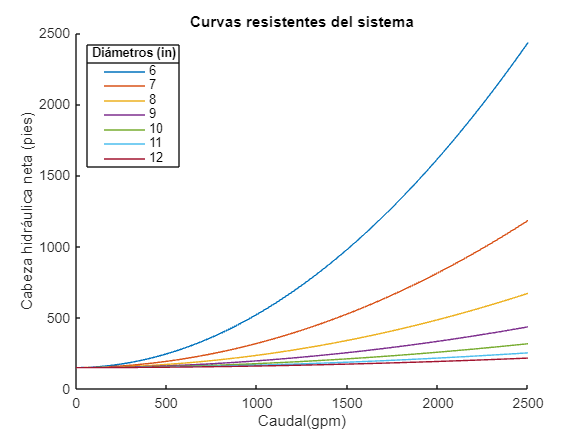

Q_plot=linspace(0,500*ceil(Q_min/500),100);             % caudal máximo redondeado a los próximos 500 gpm
for i=6:12
    d=i;
    H=cabeza(Q_plot,d*ones(1,100)); hold on;   % cálculo de cabeza para cada diámetro
    plot(Q_plot,H);                                     % graficar curva resistente
end
hold off; xlabel('Caudal(gpm)'); ylabel('Cabeza hidráulica neta (pies)');
title('Curvas resistentes del sistema');
lgd = legend('6','7','8','9','10','11','12','Location','northwest');
title(lgd,'Diámetros (in)')

## Curva de desempeño de la bomba:

Ajuste de data original a polinomio cúbico: $H=d+c\;Q+b\;Q^2 +a\;Q^3$

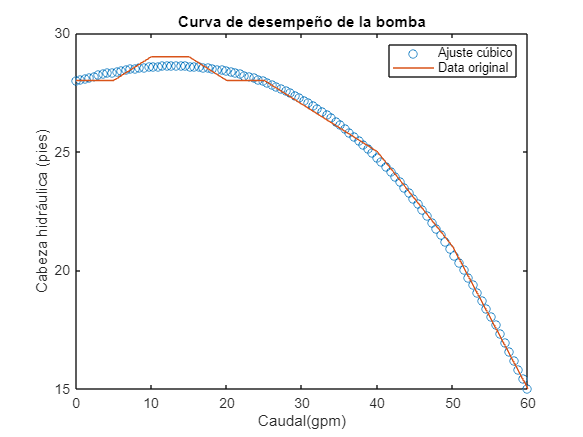

p_H = polyfit(Q_gpm,H_pies,3);     % ajuste de H vs Q usando polinomio cúbico

% graficar data original y comparar con ajuste polinomial
x = linspace(0,Q_gpm(end));
y1 = polyval(p_H,x);
plot(x,y1,'o','DisplayName','Ajuste cúbico')
hold on
plot(Q_gpm,H_pies,'DisplayName','Data original')
hold off
title('Curva de desempeño de la bomba');
xlabel('Caudal(gpm)'); ylabel('Cabeza hidráulica (pies)'); legend

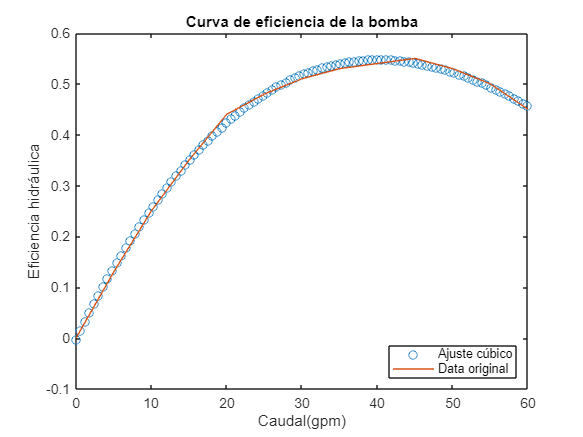



p_eta = polyfit(Q_gpm,Eta,3);     % ajuste de eta vs Q usando polinomio cúbico

% graficar data original y comparar con ajuste polinomial
y2 = polyval(p_eta,x);
plot(x,y2,'o','DisplayName','Ajuste cúbico')
hold on
plot(Q_gpm,Eta,'DisplayName','Data original')
hold off
title('Curva de eficiencia de la bomba');
xlabel('Caudal(gpm)'); ylabel('Eficiencia hidráulica'); legend('Location','southeast')

## Ley de afinidad para distintas velocidades y diámetros:

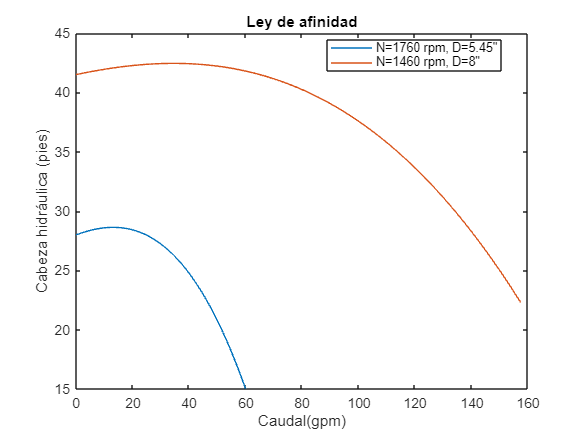

D_nominal = 5.45; N_nominal = 1760; 
N_nueva =1460; % velocidad nueva, rpm
D_nuevo =8; % diámetro nuevo del impulsor, in

Q_nueva = x*(N_nueva/N_nominal)*(D_nuevo/D_nominal)^3;      % nuevos caudales
H_nueva = y1*(N_nueva/N_nominal)^2*(D_nuevo/D_nominal)^2;   % nuevas cabezas

plot(x,y1,'DisplayName','N=1760 rpm, D=5.45"')
hold on
etiqueta=strcat('N=',num2str(N_nueva)," rpm, D=",num2str(D_nuevo),'"');
plot(Q_nueva,H_nueva,'DisplayName',etiqueta)
xlabel('Caudal(gpm)'); ylabel('Cabeza hidráulica (pies)'); legend('Location','best')
title('Ley de afinidad'); hold off;

## Optimización del diseño:

% Variables de diseño: D_tuberia,D_impulsor,N
n_var = 3;                      % número de variables
lim_inf = [12 12 900]';         % límite inferior
lim_sup = [24 36 1800]';        % límite superior
int_con = [1 2];                % diámetros de tubería en números enteros


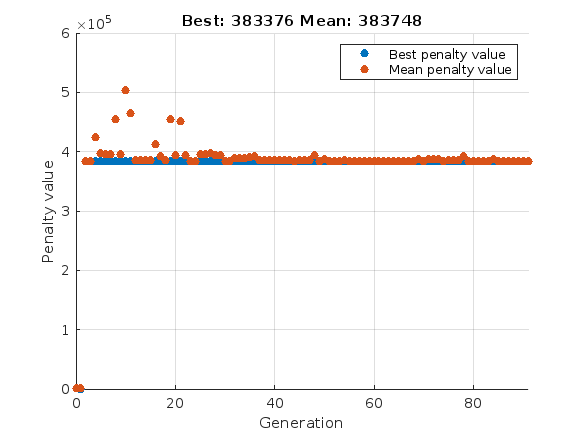

% Set nondefault solver options
options = optimoptions("ga","PopulationSize",50,"MaxGenerations",300,...
    "CreationFcn","gacreationuniformint","Display","off","PlotFcn",...
    "gaplotbestf");

% Solve
[X_opt,CT_min] = ga(@costo_total,n_var,[],[],[],[],lim_inf,...
    lim_sup,@restricciones,int_con,options);


% Clear variables
clearvars options

## Verificar factibilidad de solución:

d_opt = X_opt(1); % diámetro óptimo de la tubería, in
D_opt = X_opt(2); % diámetro óptimo del impulsor, in
N_opt = X_opt(3); % velocidad nueva, rpm

disp('DISEÑO OPTIMIZADO:')

DISEÑO OPTIMIZADO:


disp('Diámetro de la tubería (in):'); disp(d_opt);

Diámetro de la tubería (in):
    17



disp('Diámetro del impulsor (in):'); disp(D_opt);

Diámetro del impulsor (in):
    24



disp('Velocidad angular (rpm):'); disp(N_opt);

Velocidad angular (rpm):
   1.0518e+03



disp('Costo total (USD):'); disp(CT_min)

Costo total (USD):
   3.8338e+05




Q_opt = x*(N_opt/N_nominal)*(D_opt/D_nominal)^3;            % caudal
H_bomba = y1*(N_opt/N_nominal)^2*(D_opt/D_nominal)^2;       % cabeza de la bomba
H_sistema = cabeza(Q_opt,X_opt(1)*ones(1,length(Q_opt)));   % cabeza del sistema

figure
plot(Q_opt,H_bomba,'DisplayName','Curva de desempeño de la bomba')
hold on; title('Curvas de cabeza vs caudal');
plot(Q_opt,H_sistema,'DisplayName','Curva resistente del sistema');     % graficar curva resistente
xlabel('Caudal(gpm)'); ylabel('Cabeza hidráulica (pies)'); legend('Location','best');

disp('Punto de operación:')

Punto de operación:


q = 45*(N_opt/N_nominal)*(D_opt/D_nominal)^3          % caudal óptimo

q = 2.2966e+03

h = 23*(N_opt/N_nominal)^2*(D_opt/D_nominal)^2        % cabeza óptima

h = 159.2972

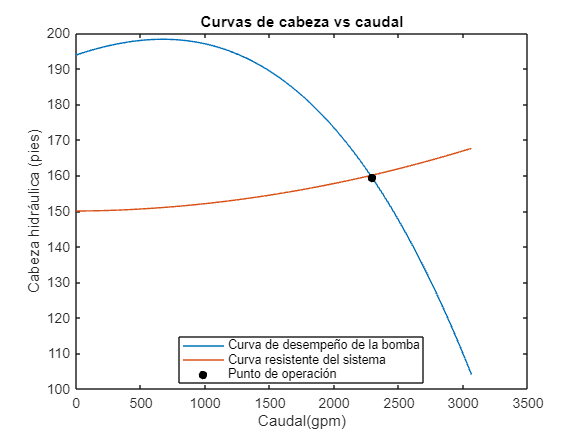

scatter(q,h,'filled','k','DisplayName','Punto de operación')

## Función - Costo total

En base a trasladar el punto original de máxima eficiencia: $Q=45\;\textrm{gpm},H=23\;\textrm{pies},\;\eta =55%$, aplicando la ley de afinidad:

function CT=costo_total(X)

D_tuberia=X(1); D_impulsor=X(2); N=X(3);   % variables de diseño

% Punto de operación (ley de afinidad)
D_base = 5.45; N_base = 1760; eta = 0.55; Q_base = 45; H_base = 23;

Q = Q_base*(N/N_base).*(D_impulsor/D_base).^3;       % caudal (gpm)
H = H_base*(N/N_base).^2.*(D_impulsor/D_base).^2;    % cabeza (pies)
t = (1.5E6./Q)/60;                                   % tiempo de operación requerido (h/día)

% Consumo energético (costo operativo)
Q_cfs=Q./448.831169;                        % flujo, gpm -> pie³/s
W_hp=(1.94*32.17*H.*Q_cfs/eta)/550;         % potencia de la bomba, hp
CO = 5*365*t.*(W_hp*0.735499)*0.10;         % costo de la energía durante 5 años

% Inversión (costo capital)
C_motobomba = 3500+1500*D_impulsor;
C_valvula = 300+200*D_tuberia;
C_codos = 50+50*D_tuberia;
L = 5280*0.8+150;
C_tuberia = 1*D_tuberia;
CI = C_motobomba+4*C_valvula+10*C_codos+C_tuberia*L;    %inversión

% Costo total
CT = CI + CO;
end

## Función - Cabeza hidráulica del sistema

function H=cabeza(Q_gpm,D_tuberia)

global sK_total %#ok<GVMIS> 

%% Datos conocidos
Q=Q_gpm./448.831169;        % flujos, gpm -> pie³/s
L=5280*0.8+150;             % longitud, pie
dz=150;                     % diferencia de altura, pie
D=D_tuberia./12;            % diámetros, in -> pie
eD=(0.000492126)./D;        % rugosidad relativa (hierro galvanizado)
rho=1.94;                   % densidad de agua @ 20C, slug/pie³
mu=2.73E-5;                 % viscosidad de agua @ 20C, slug/(pie*s)
g=32.17;                    % aceleración de la gravedad, pie/s²

%% Variables secundarias
V=Q./(pi/4*D.^2);
Re=rho*4*Q./(pi*(mu)*D);                        % número de Reynolds
fD=(0.2479-0.0000947*(7-log10(Re)).^4)./...
    (log10(eD./3.615+7.366./Re.^0.9142)).^2;    % factor Darcy
hF=8*fD.*L.*Q.^2./(g*pi^2.*D.^5);               % pérdidas mayores (Darcy–Weisbach)

hF(isnan(hF))=0;                                % eliminar error en Q = 0;

H = hF+dz+sK_total*V.^2./(2*g);                 % cabeza hidráulica total
end

## Función - Restricciones de diseño

function [c,ceq] = restricciones(X)

D_tuberia=X(1); D_impulsor=X(2); N=X(3);   % variables de diseño

% Punto de operación (ley de afinidad)
D_base = 5.45; N_base = 1760; Q_base = 45; H_base = 23;

Q = Q_base*(N/N_base).*(D_impulsor/D_base).^3;             % caudal (gpm)
Hbomba = H_base*(N/N_base).^2.*(D_impulsor/D_base).^2;     % cabeza (pies)

t = (1.0E6./Q)/60;   % tiempo de para llenar el tanque (h)
c(1) = t - 8;          % restricción de t <= 8 h

Hsist=cabeza(Q,D_tuberia);

% restricción de igualdad entre cabeza del sistema y de la bomba
dH = 0.5e-2*Hbomba;     % Error admisible 0.5%
c(2) = abs(Hbomba - Hsist)-dH; ceq=[];
end
